# CoP動揺分析　複数試行・複数被験者を一度に

※　Demo03 までは理解しておくこと

式が無効です。不足している文字または余分な文字をチェックしてください。

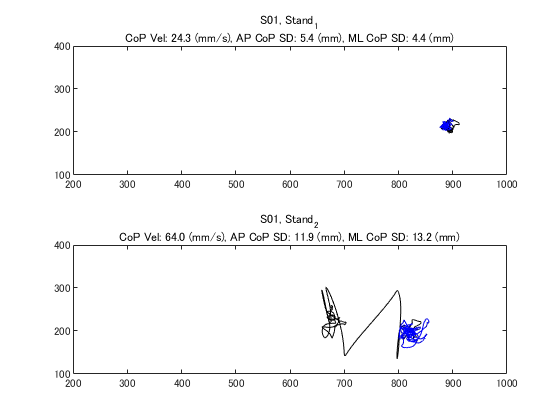

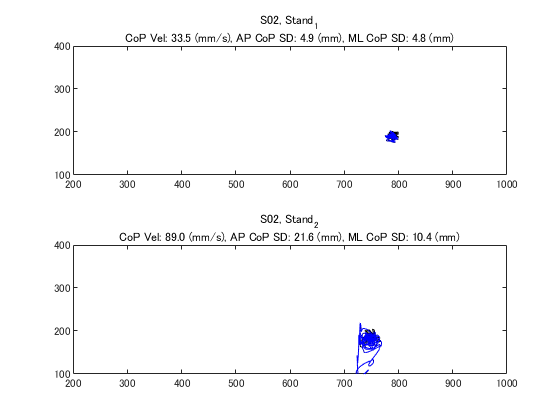

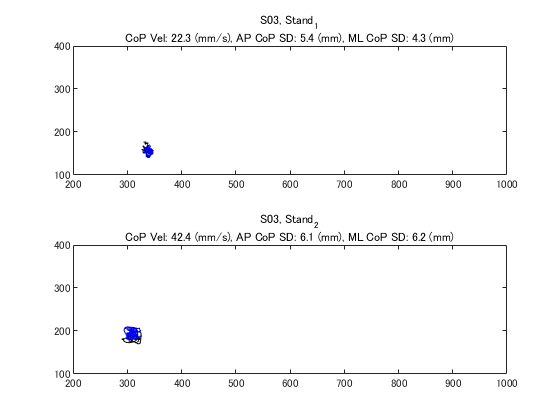

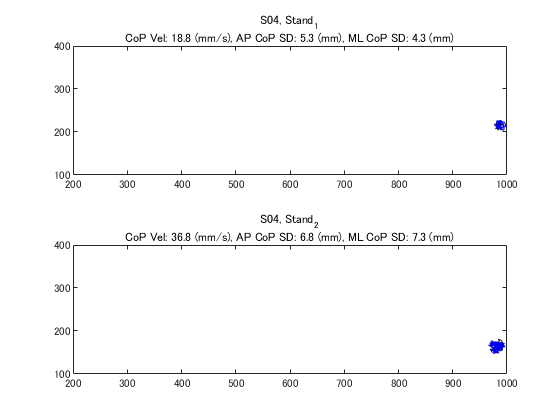

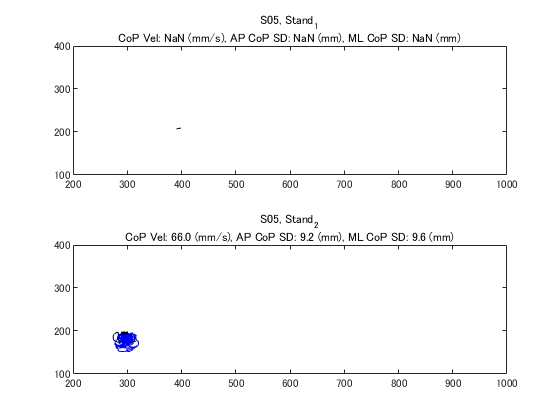

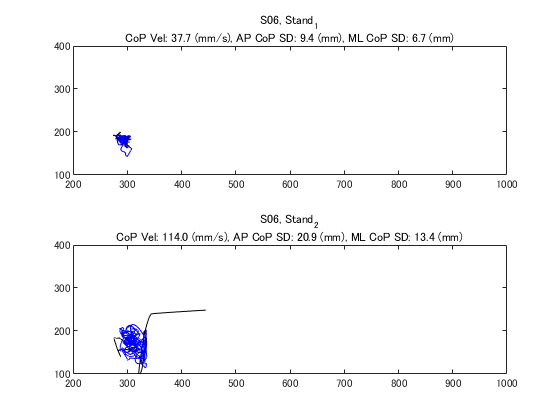

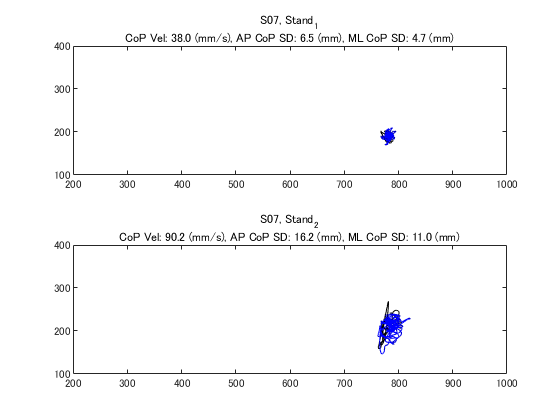

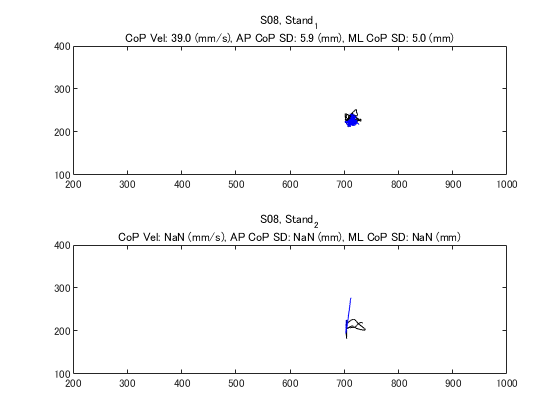

clear
close all
clc

% 分析する条件名（DataStruct内のフィールド名）
ConditionNameArray = {'Stand_1', 'Stand_2'} ;

% 分析区間を設定
% 静止立位のCoP動揺分析の場合、通常 20s 程度の区間を分析する
% "静止立位の定常状態"が保たれている区間を分析する必要がある
%
% % 途中で片脚立ちが維持できなくなる等しているデータは、
% 除外するなど適切に取り扱う必要があるので細心の注意を払うこと
dur = 20000 ;
fStart = 2001 ;
fEnd = fStart + dur - 1 ; 


for iSubject = 1:20
    
    % *** 実験実習で測定計測したデータ を load***
    fileName = sprintf('Data_S%02d', iSubject) ;
    load(fileName) ;
    
    figure(iSubject) ;
        
    
    for iCondition = 1:length(ConditionNameArray) 
        
        % cop データを抽出
        conditionName = ConditionNameArray{iCondition} ;
        cop = DataStruct.(conditionName).CoP ;
        copX = cop(:,1) ;
        copY = cop(:,2) ;
        
        % // CoP　指標の分析。右辺に適切な分析コードを書くこと //
        % CoP velocity: 単位時間あたりのCoP軌跡長 (mm/s)
        copDis = 
        copVel = 
        
        % CoP SD
        copSDAP = 
        copSDML = 
        
        % ////

        % 必ずプロットを確認して、異常がないか確認すること
        subplot(2,1,iCondition) ;
        plot(copX, copY, 'k') ; hold on
        plot(copX(fStart:fEnd), copY(fStart:fEnd), 'b')
        
        set(gca, 'xlim', [200,1000], 'ylim', [100, 400])
        title({[sprintf('S%02d, ', iSubject), conditionName];...
               sprintf('CoP Vel: %0.1f (mm/s), AP CoP SD: %0.1f (mm), ML CoP SD: %0.1f (mm)', copVel, copSDAP, copSDML)})
        
        % figure を保存
        filePath = sprintf('Demo12_CoPFigures/CoPFig_S%02d', iSubject) ;
        saveas(gcf, filePath, 'png')
        
        %　エキスポート用の構造体とテーブル
        S(iSubject).(['CopVel_', conditionName]) = copVel ;
        S(iSubject).(['APCoPSD_', conditionName]) = copSDAP ;
        S(iSubject).(['MLCoPSD_', conditionName]) = copSDML ;
        
    end
end

## エキスポート用の構造体とテーブル

array editor から、テーブルの数値をコピーして Excel 等に貼り付けてもよいし、writetable関数を用いて、テーブルをcsvファイルに保存してもよい。

統計検定を行う前に、プロットを確認して、分析された数値が正しいものであるか、必ず確認すること


T = struct2table(S)

T = 20×6 table
    CopVel_Stand_1    APCoPSD_Stand_1    MLCoPSD_Stand_1    CopVel_Stand_2    APCoPSD_Stand_2    MLCoPSD_Stand_2
    ______________    _______________    _______________    ______________    _______________    _______________

        24.307            5.4197             4.4347             63.986            11.882             13.192     
        33.547             4.851             4.8182             89.027            21.593             10.426     
        22.319            5.4307             4.2577             42.408            6.1356             6.2339     
         18.82            5.3225             4.2568             36.789            6.7872             7.3243     
           NaN               NaN                NaN             66.045            9.2047              9.565     
        37.731            9.3943             6.6666             114.01            20.886             13.369     
        38.044            6.5443             4.7325             90.242          